Stability Analysis for a Discrete-time LTI system using Lyapunov's criteria.

First, we define a system using its transfer function in continuous time and we applied a step to obtain Tr (rise time) so we can apply the discretization process without losing the system integrity.

clear all; close all;
num = 1;
den = [1 0.1 1]; % STABLE CASE
% den = [1 -0.1 1]; % UNSTABLE CASE
G = tf(num,den)

G =
 
         1
  ---------------
  s^2 + 0.1 s + 1
 
Continuous-time transfer function.
Model Properties


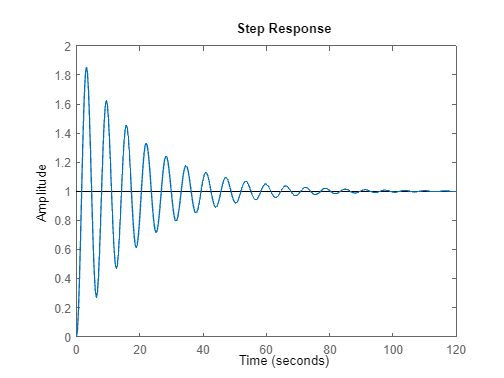

step(G)

step_info = stepinfo(G);
Tr = getfield(step_info,'RiseTime');

As it's observed from the previous informations, the system rise time corresponds to 1.0832 s. Thus, we define the Ts (sampling time) for the discretization process as

 
$$T_{r}=10\cdot T_{s} \therefore T_{s} = T_{r} /10
$$


Ts = Tr/10;

And, then, we convert the plant from continuous to discrete time using the Zero-order hold (zoh) discretization method:

Gd = c2d(G,Ts,'zoh')

Gd =
 
   0.00584 z + 0.005819
  ----------------------
  z^2 - 1.978 z + 0.9892
 
Sample time: 0.10832 seconds
Discrete-time transfer function.
Model Properties


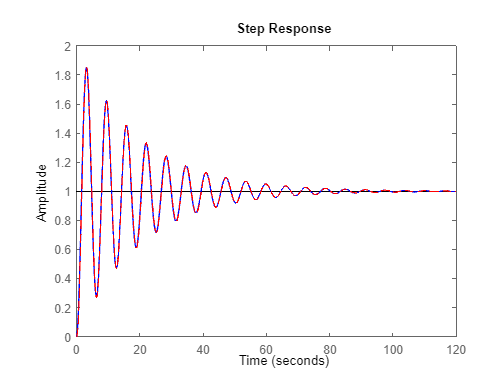

step(G,'b',Gd,'r--')

Now, we convert the transfer function parameters to state-space form, so we can apply Lyapunov's formulation to the study case:

[num,den] = tfdata(Gd);
num = cell2mat(num);
den = cell2mat(den);
[A,B,C,D] = tf2ss(num,den)

A =     1.9776   -0.9892
    1.0000         0


B =      1
     0


C =     0.0058    0.0058


D = 0

The Lyapunov Stability analysis for discrete-time systems is implemented for our study case:


$$A^{T}PA-P< 0,P>0$$


P = sdpvar(length(A));      % alocating an space in the computer space to a symbolic decision variable
sdisplay(P);

LMI1 = [A'*P*A-P<=0];       % defining the constraint
LMI2 = [P>=0];              % defining the constraint

LMI = [LMI1,LMI2];          % concatenating the LMIs

optimize(LMI);              % solving the optimization problem using Semidefinite Programming (SDP)

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 5, dim = 9, blocks = 3
nnz(A) = 10 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.38E+01 0.000
  1 :   0.00E+00 1.50E+00 0.000 0.0630 0.9900 0.9900   1.00  1  0  6.2E-01
  2 :   0.00E+00 1.43E-01 0.000 0.0957 0.9900 0.9900   1.00  1  1  6.0E-02
  3 :   0.00E+00 2.69E-02 0.000 0.1875 0.9000 0.9000   1.00  1  1  1.1E-02
  4 :   0.00E+00 7.20E-03 0.000 0.2677 0.9000 0.9000   1.00  1  1  3.0E-03
  5 :   0.00E+00 2.33E-03 0.000 0.3240 0.9000 0.9000   1.00  1  1  9.7E-04
  6 :   0.00E+00 2.14E-04 0.000 0.0916 0.9900 0.9900   1.00  1  1  8.9E-05
  7 :   0.00E+00 1.78E-05 0.000 0.0832 0.9900 0.9900   1.00  1  1  7.4E-06
  8 :   0.00E+00 1.47E-06 0.000 0.0826 0.9900 0.9900   1.00  1  1  6.1E-07
  9 :   0.00E+00 1.20E-07 0.000 0.0818 0.9900 0.9900   1.00  1  1  5.0E-08
 10 :   0.00E+00 9.73

Then, we need to check if the initial conditions were satisfied:

Ps = value(P);              % extract the numerical result of the sdpvar obtained by the previous operation
eig_A = eig(A)

eig_A =    0.9888 + 0.1074i
   0.9888 - 0.1074i


eig_LMI1 = eig(A'*Ps*A-Ps)

eig_LMI1 =    -0.0502
   -0.0001


eig_LMI2 = eig(Ps)

eig_LMI2 =     0.0121
    3.9374


A command that can be used to obtain the all the privous information is

**checkset(LMI);**

we also can use 

**double(P);**

to extract the numerical result of the sdpvar